timems = loco(:,1)

timems = 300000×1 table
    Timems
    ______

       0  
       1  
       2  
       3  
       4  
       5  
       6  
       7  
       8  
       9  
      10  
      11  
      12  
      13  
      14  
      15  


locov = loco(:,2)

locov = 300000×1 table
    AI5_violet
    __________

      3.9853  
      3.9854  
      3.9857  
      3.9853  
      3.9848  
      3.9853  
      3.9853  
       3.985  
      3.9851  
      3.9851  
      3.9845  
      3.9854  
      3.9853  
      3.9845  
      3.9853  
      3.9851  


locoa = table2array(loco)

locoa = 	1.0e+05 *

         0    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000


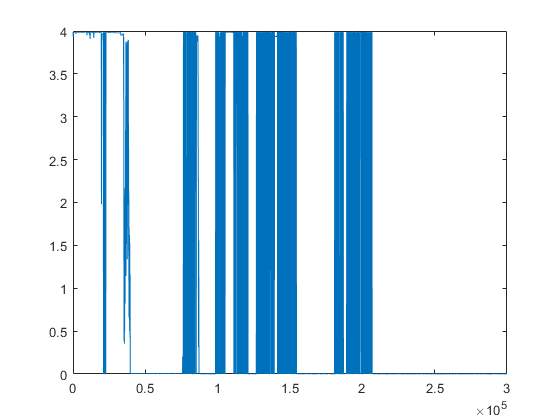

plot (locoa(:,1), locoa(:,2))

### Extract Velocity v26.a

%% velocity
% Define Wheel Statistics
Radius  = 11.06; %radus in cm
noftabs = 30; %number of tabs
circumference = 2*pi*Radius;
distpertab =circumference/(2*noftabs); %distance per tab (tabs are evenly spaced and the wheel is split equally)
samplerate = 1000; %aquisition rate
twindow = samplerate; %window in miliseconds

opto = locoa(:,2)

opto =     3.9853
    3.9854
    3.9857
    3.9853
    3.9848
    3.9853
    3.9853
    3.9850
    3.9851
    3.9851


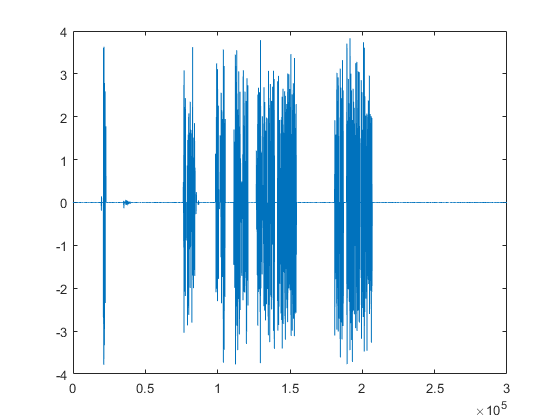


%Look at derivative of wheel trace
diffSC = diff(opto); %derivative of the square pulses
figure; plot(1:1:length(opto)-1,diffSC) %plot

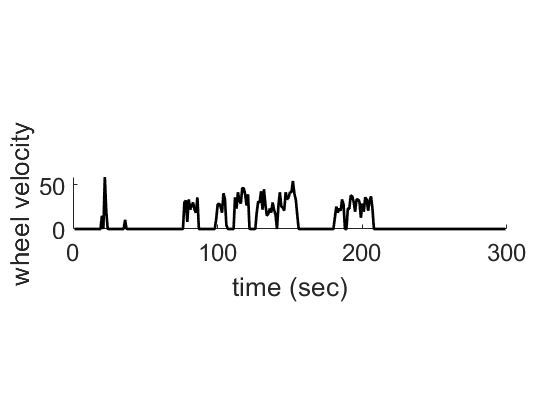


%define likely break points and binarize
triggerframes = find(abs(diffSC)>=mean(diffSC)+std(diffSC)); %find where there was probably a change from blocked to open
tabtransittimes = zeros(1,length(opto)); %make an empty matrix
tabtransittimes(triggerframes)= 1; %binarize the transitions

%sum transitions over the window
j=1;
for i=1:twindow:length(opto)-twindow
    numbreaks(j) = sum(tabtransittimes(i:i+twindow));
    j=j+1;
end

velocity = numbreaks * distpertab; %gives approximate velocity at ege of wheel
burstStats.velocity = velocity;

figure; hold on;
subplot(5,1,3); hold on;
plot(1:length(numbreaks),velocity, 'LineWidth',2,'Color','k')
ylabel('wheel velocity')
xlabel('time (sec)')
set(gca,'FontSize',18)

axis([0 length(epercEvts) 0 max(velocity)+5])

Unrecognized function or variable 'epercEvts'.

### Extract pupil v26.a

Pupildata

length(Pupildata)

ans = 9000

v26a.pupil = zeros(length(Pupildata), 1)

v26a = struct with fields:
    pupil: [9000×1 double]


v26a.pupil

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Pupildata{1,900}

ans = struct with fields:
       rotated_rect: [18.0930 44.0805 44.3332 54.1015 21.1758]
             center: [279.0930 141.0805]
            major_r: 54.1015
           frame_id: 900
    frame_intensity: 19.8642
            contour: [53×1×2 int16]


isfield(Pupildata{1,3105}, 'frame_id')

ans = logical
   1


isfield(Pupildata{1,3105}, 'major_r')

ans = logical
   0


for ii = 1:length(Pupildata)
    %disp(ii)
    if isfield(Pupildata{1,ii}, 'major_r') == 0
        sprintf('major_r not found at index %d', ii)
        continue
    end
    v26a.pupil(ii) = Pupildata{1,ii}.major_r;
end

ans = 'major_r not found at index 3105'

ans = 'major_r not found at index 3106'

ans = 'major_r not found at index 3107'

ans = 'major_r not found at index 3108'

ans = 'major_r not found at index 3109'

ans = 'major_r not found at index 3110'

ans = 'major_r not found at index 3111'

ans = 'major_r not found at index 3112'

ans = 'major_r not found at index 3113'

ans = 'major_r not found at index 3114'

ans = 'major_r not found at index 3115'

ans = 'major_r not found at index 3116'

ans = 'major_r not found at index 3117'

ans = 'major_r not found at index 3119'

ans = 'major_r not found at index 3120'

ans = 'major_r not found at index 3121'

ans = 'major_r not found at index 3122'

ans = 'major_r not found at index 3123'

ans = 'major_r not found at index 3124'

ans = 'major_r not found at index 3125'

ans = 'major_r not found at index 3126'

ans = 'major_r not found at index 3127'

ans = 'major_r not found at index 3128'

ans = 'major_r not found at index 3399'

ans = 'major_r not found at index 3400'

ans = 'major_r not found at index 3401'

ans = 'major_r not found at index 3402'

ans = 'major_r not found at index 3403'

ans = 'major_r not found at index 3404'

ans = 'major_r not found at index 3405'

ans = 'major_r not found at index 3406'

ans = 'major_r not found at index 3407'

ans = 'major_r not found at index 3408'

ans = 'major_r not found at index 3409'

ans = 'major_r not found at index 3410'

ans = 'major_r not found at index 3411'

ans = 'major_r not found at index 3412'

ans = 'major_r not found at index 3413'

ans = 'major_r not found at index 3414'

ans = 'major_r not found at index 3416'


v26a.pupil

ans =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


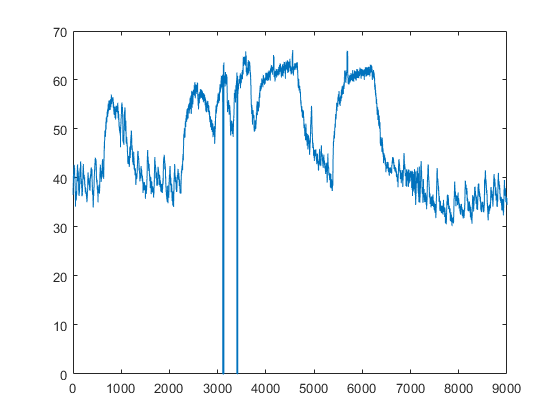

plot (v26a.pupil)

### Extract %FOV active

allEvtLocs = cell2mat(res.fts.loc.x2D'); %%% extract all event locs
allEvtLocs

allEvtLocs =        70360
       70361
       70362
       70363
       70860
       70872
       70873
       70874
       70875
       70876


uLocs = unique(allEvtLocs);




numPix = length(uLocs); %number of pixels where an event occupied
sizeT = zeros(length(tLocs),frames);

Unrecognized function or variable 'tLocs'.


for i = 1:length(tLocs)
    clear uT
    uT = unique(tLocs{i});

    if ~isempty(uT)

        if length((out.pixelSizePerFrame{jj}{i}(1:end,1))) == length(uT)
        
            sizeT(i,uT) = ((out.pixelSizePerFrame{jj}{i}(1:end,1)) / (spRes^2));
            
        end
    end
end



sizeEvts = sum(sizeT,1);
percEvts = (sizeEvts ./ numPix) * 100

percEvts

Trying with 'out'

dir = 'C:\Users\camer\Box\CMH\.repos\pfc\data\by.trial\v26\a\121219_V26_54um_2x-000_video\'

dir = 'C:\Users\camer\Box\CMH\.repos\pfc\data\by.trial\v26\a\121219_V26_54um_2x-000_video\'


out = readFts(dir)

     1

below
121219_V26_54um_2x-000_video_aqua


out = struct with fields:
                    dffMat: {[14×540 single]}
                     xSize: {[512]}
                     ySize: {[512]}
                     zSize: {[540]}
                  datNames: {'121219_V26_54um_2x-000_video_aqua'}
                  propGrow: {{1×14 cell}}
           propGrowOverall: {[14×4 double]}
    propSpeedPerFrameDArea: {{1×14 cell}}
         propSpeedPerFrame: {{1×14 cell}}
                       dff: {[1.2398 1.3214 1.1374 1.3417 1.1915 1.2762 1.3369 1.5881 1.6021 2.0059 1.2467 13.7926 2.3240 1.4949]}
               dffMaxFrame: {[219 115 358 233 223 222 235 234 233 233 228 319 233 220]}
                   dffRise: {[2.7789 4.4463 4.4463 1.1116 3.3347 1.1116 1.1116 1.1116 1.1116 0.5558 1.6674 0.5558 0.5558 0.5558]}
                   dffFall: {[2.2231 3.3347 1.1116 1.6674 1.6674 1.1116 1.6674 1.6674 1.1116 1.1116 0.5558 0.5558 0.5558 1.1116]}
         pixelSizePerFrame: {{1×14 cell}}
                        t0: {[213 107 349 231 218 220 233 232 2

Set resoltions etc

spRes = 0.80718154623606

spRes = 0.8072

tres = 0.55578697729921

tres = 0.5558

detection 

    A = length(out.datNames);
    clear bursts burstStats

    for jj = 1:A
        
        %% Frame size and video f length  
            frames = out.zSize{jj};
            xSize = out.xSize{jj};
            ySize = out.ySize{jj};
            zSize = frames;
    
        %% Absolute locations of all events
            clear aLocs aLocsB xLocs yLocs tLocs
            for i = 1:length(out.locAbs{jj})
                absLocsB = out.locAbs{jj};
                aLocs = absLocsB{i}; %single event
                [xLocs{i} yLocs{i} tLocs{i}] = (ind2sub([xSize ySize zSize], aLocs));
                xLocs{i} = xSize-xLocs{i};
            end
        
        %% Set Zero arrays for curve BW and sizeT -- what are these for?
                % What do these correspond to ... 
            curveBW = zeros(length(tLocs),frames);
            sizeT = zeros(length(tLocs),frames);
        
        

        %% Number of onsets per frame
            clear growthT
            growthT = zeros(length(tLocs),frames);
            for i = 1:length(tLocs) %#events
                clear uT %uT is always 2 frames shorter than fts.propGrow
                uT = unique(tLocs{i}); %time points of an event
                if ~isempty(uT)
                    minuT = min(uT); %just the first frame of an event
                    curveBW(i,minuT) = 1;
                    k=1;
                    for j =2:length(uT)
                        if nansum(out.propGrow{jj}{i}(j,:)) == 0
                            growthT(i,uT(k)) = 0;
                        else
                            growthT(i,uT(k)) = nansum(out.propGrow{jj}{i}(j,:));
                        end
                        k=k+1;
                    end
                end
            end
            
            numEvts = sum(curveBW,1);
            burstStats.numEvts{jj} = numEvts;
            growthEvts = sum(growthT,1);
            X = growthEvts(growthEvts > 0)';
            
            
            f = figure(jj);
            screen_size = get(0, 'ScreenSize');
            set(f, 'Position', ...
                [screen_size(3)/20 ...
                screen_size(4)/20 ...
                screen_size(3)*9/10 ...
                screen_size(4)*8.5/10]);
            
        
        %% Percent area with event activity
            clear allEvtLocs uLocs
            allEvtLocs = cell2mat(out.loc2D{jj}'); %%% extract all event locs
            uLocs = unique(allEvtLocs);
            
            

            
            numPix = length(uLocs); %number of pixels where an event occupied
            sizeT = zeros(length(tLocs),frames);
            
            for i = 1:length(tLocs)
                clear uT
                uT = unique(tLocs{i});

                if ~isempty(uT)

                    if length((out.pixelSizePerFrame{jj}{i}(1:end,1))) == length(uT)
                    
                        sizeT(i,uT) = ((out.pixelSizePerFrame{jj}{i}(1:end,1)) / (spRes^2));
                        
                    end
                end
            end
            

            
            sizeEvts = sum(sizeT,1);
            percEvts = (sizeEvts ./ numPix) * 100;
            burstStats.percEvts{jj} = percEvts;
        
        
    
        
        %% find burst periods: >1% %FOV, >25 frames apart, >25% max #events 
            thr = 1;
            [xPeaks,maxPkTimes] = findpeaks(percEvts,'MinPeakHeight',thr,'MinPeakDistance',25);
            
            pp = zeros(numel(xPeaks),2);  % 10%, 90% by start/end
            thrVec = [0.1];
        
        %% Baseline Detection
            % Baseline Number of Events
                    % Taking the mode of number of events that != 0. Having the mode
                    % = to zero will cause problems down the line
                    numEvts_mode =  numEvts(numEvts ~= 0);
                    base.numEvts =  mode(numEvts_mode);
                    
                % Baseline percEvts
                        % Taking baseline percEvts based on the frames with mode # of
                        % events
                    percEvts_mode = percEvts(numEvts == base.numEvts);
                    percEvts_mode_mean = mean(percEvts_mode);
                    base.percEvts = percEvts_mode_mean;
    end

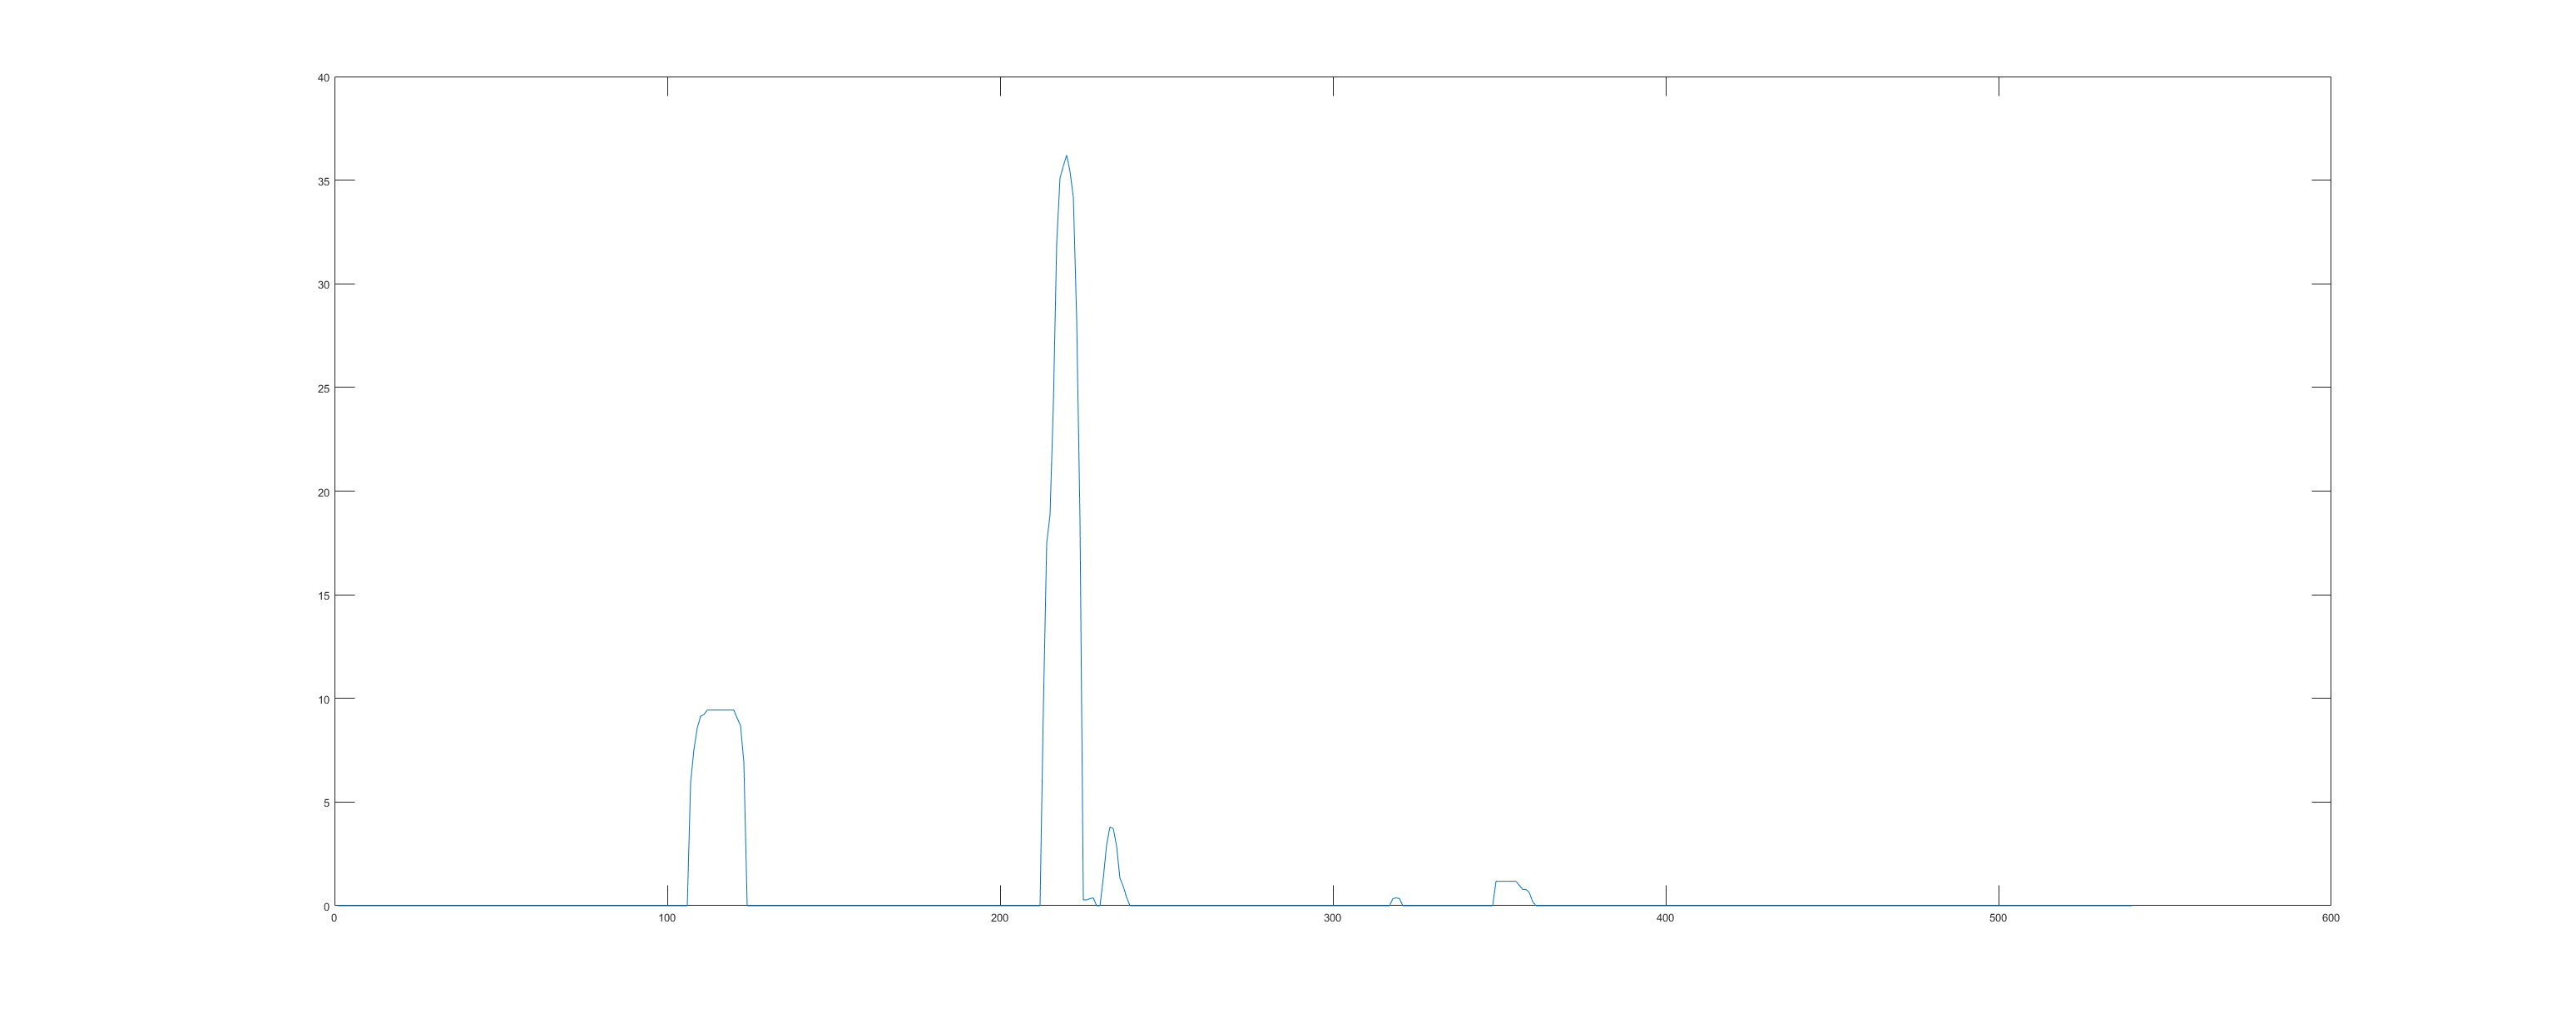

plot(percEvts)

percframetimes = 0:tres:300

percframetimes =          0    0.5558    1.1116    1.6674    2.2231    2.7789    3.3347    3.8905    4.4463    5.0021    5.5579    6.1137    6.6694    7.2252    7.7810    8.3368    8.8926    9.4484   10.0042   10.5600   11.1157   11.6715   12.2273   12.7831   13.3389   13.8947   14.4505   15.0062   15.5620   16.1178   16.6736   17.2294   17.7852   18.3410   18.8968   19.4525   20.0083   20.5641   21.1199   21.6757   22.2315   22.7873   23.3431   23.8988   24.4546   25.0104   25.5662   26.1220   26.6778   27.2336


percframetimes

percframetimes =          0    0.5558    1.1116    1.6674    2.2231    2.7789    3.3347    3.8905    4.4463    5.0021    5.5579    6.1137    6.6694    7.2252    7.7810    8.3368    8.8926    9.4484   10.0042   10.5600   11.1157   11.6715   12.2273   12.7831   13.3389   13.8947   14.4505   15.0062   15.5620   16.1178   16.6736   17.2294   17.7852   18.3410   18.8968   19.4525   20.0083   20.5641   21.1199   21.6757   22.2315   22.7873   23.3431   23.8988   24.4546   25.0104   25.5662   26.1220   26.6778   27.2336


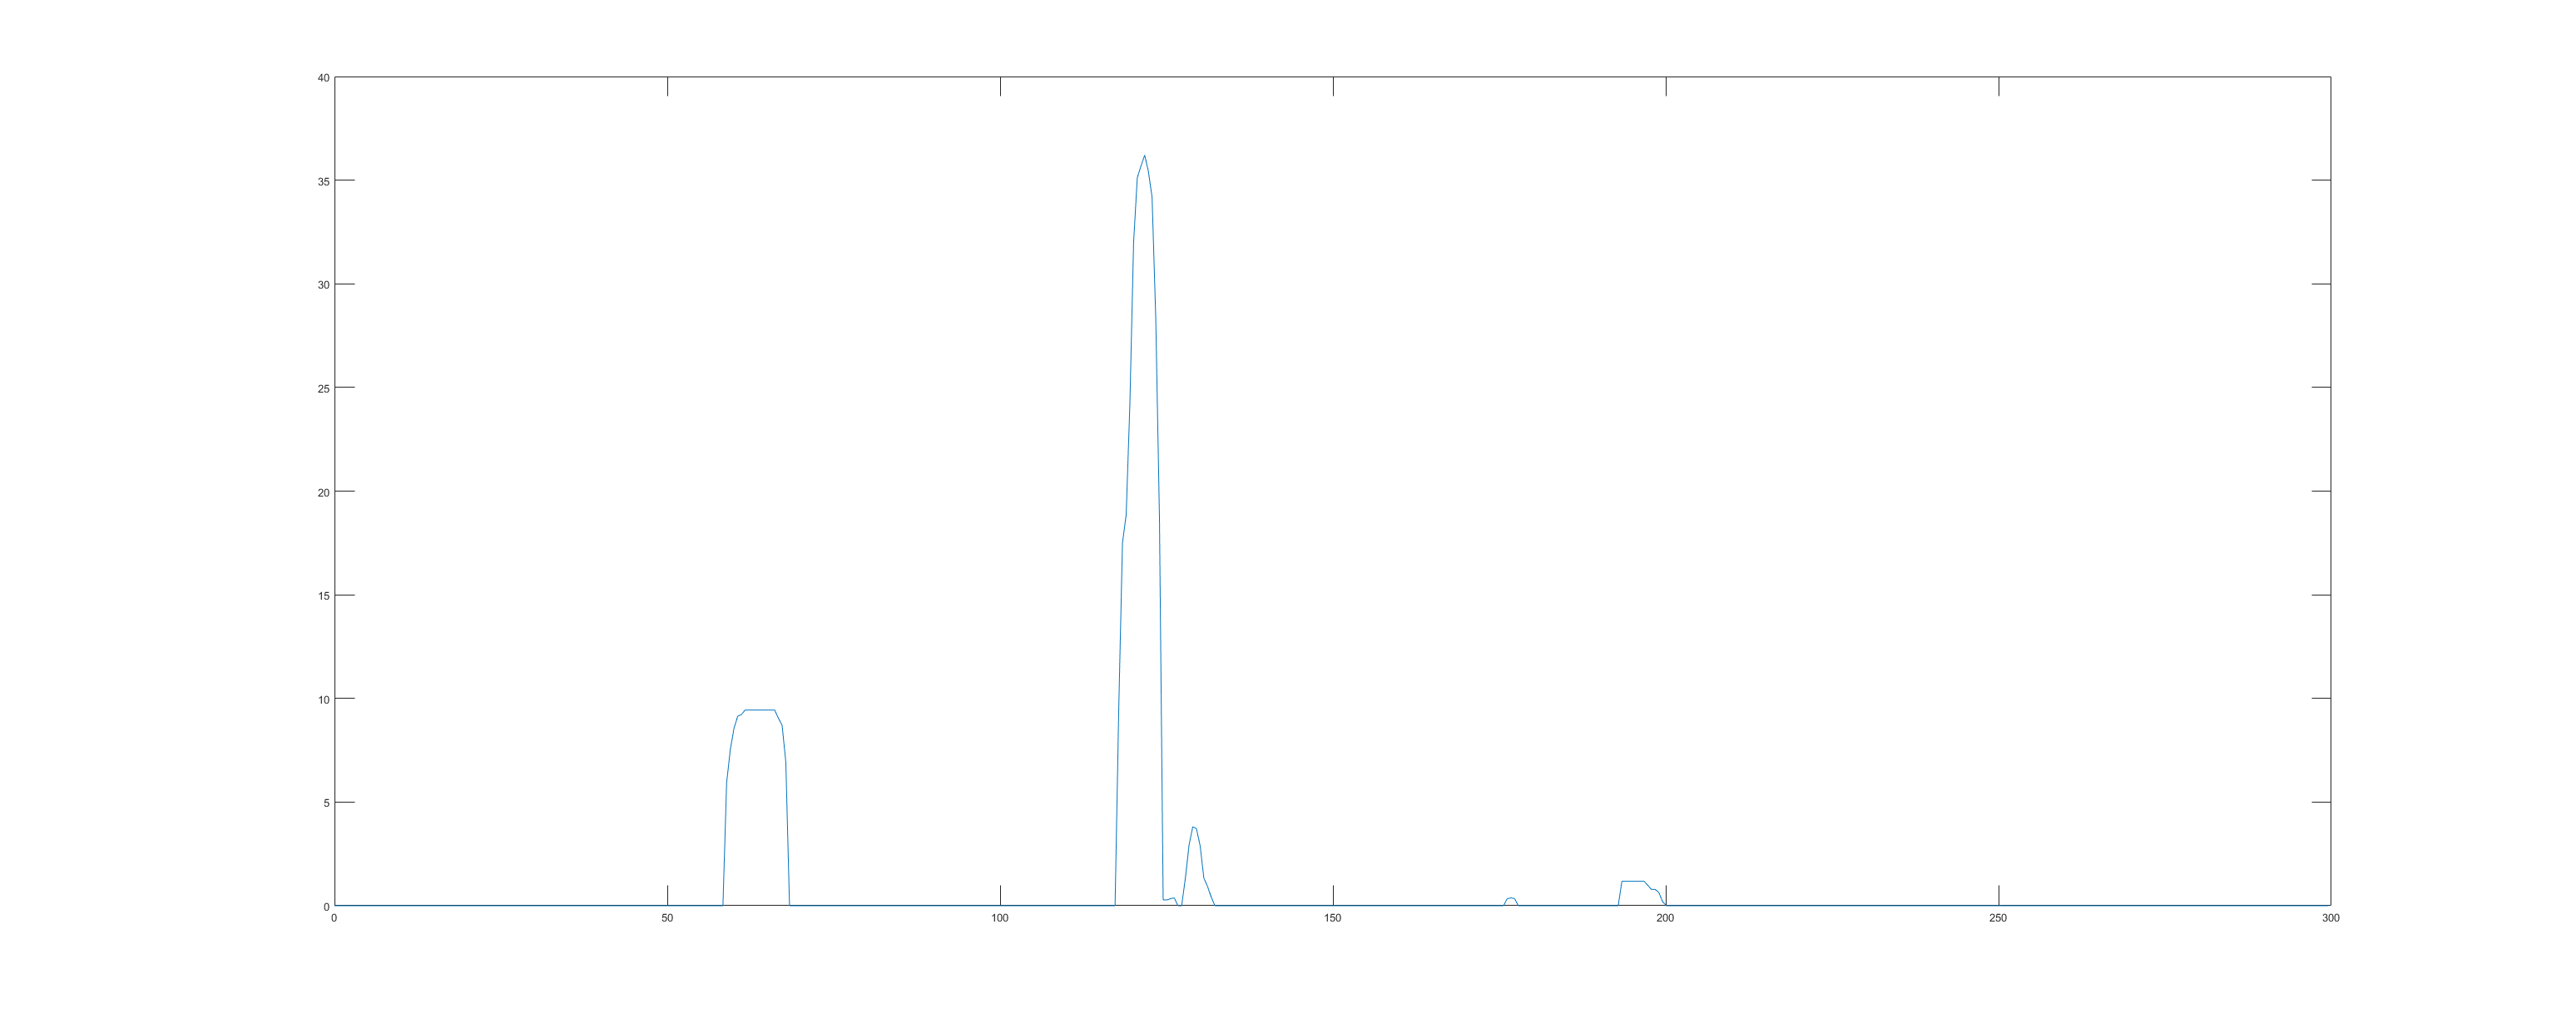

plot(percframetimes, percEvts)

pupilframetimes = 0.033333333333:0.0333333333333:300

pupilframetimes =     0.0333    0.0667    0.1000    0.1333    0.1667    0.2000    0.2333    0.2667    0.3000    0.3333    0.3667    0.4000    0.4333    0.4667    0.5000    0.5333    0.5667    0.6000    0.6333    0.6667    0.7000    0.7333    0.7667    0.8000    0.8333    0.8667    0.9000    0.9333    0.9667    1.0000    1.0333    1.0667    1.1000    1.1333    1.1667    1.2000    1.2333    1.2667    1.3000    1.3333    1.3667    1.4000    1.4333    1.4667    1.5000    1.5333    1.5667    1.6000    1.6333    1.6667


Try plotting all together

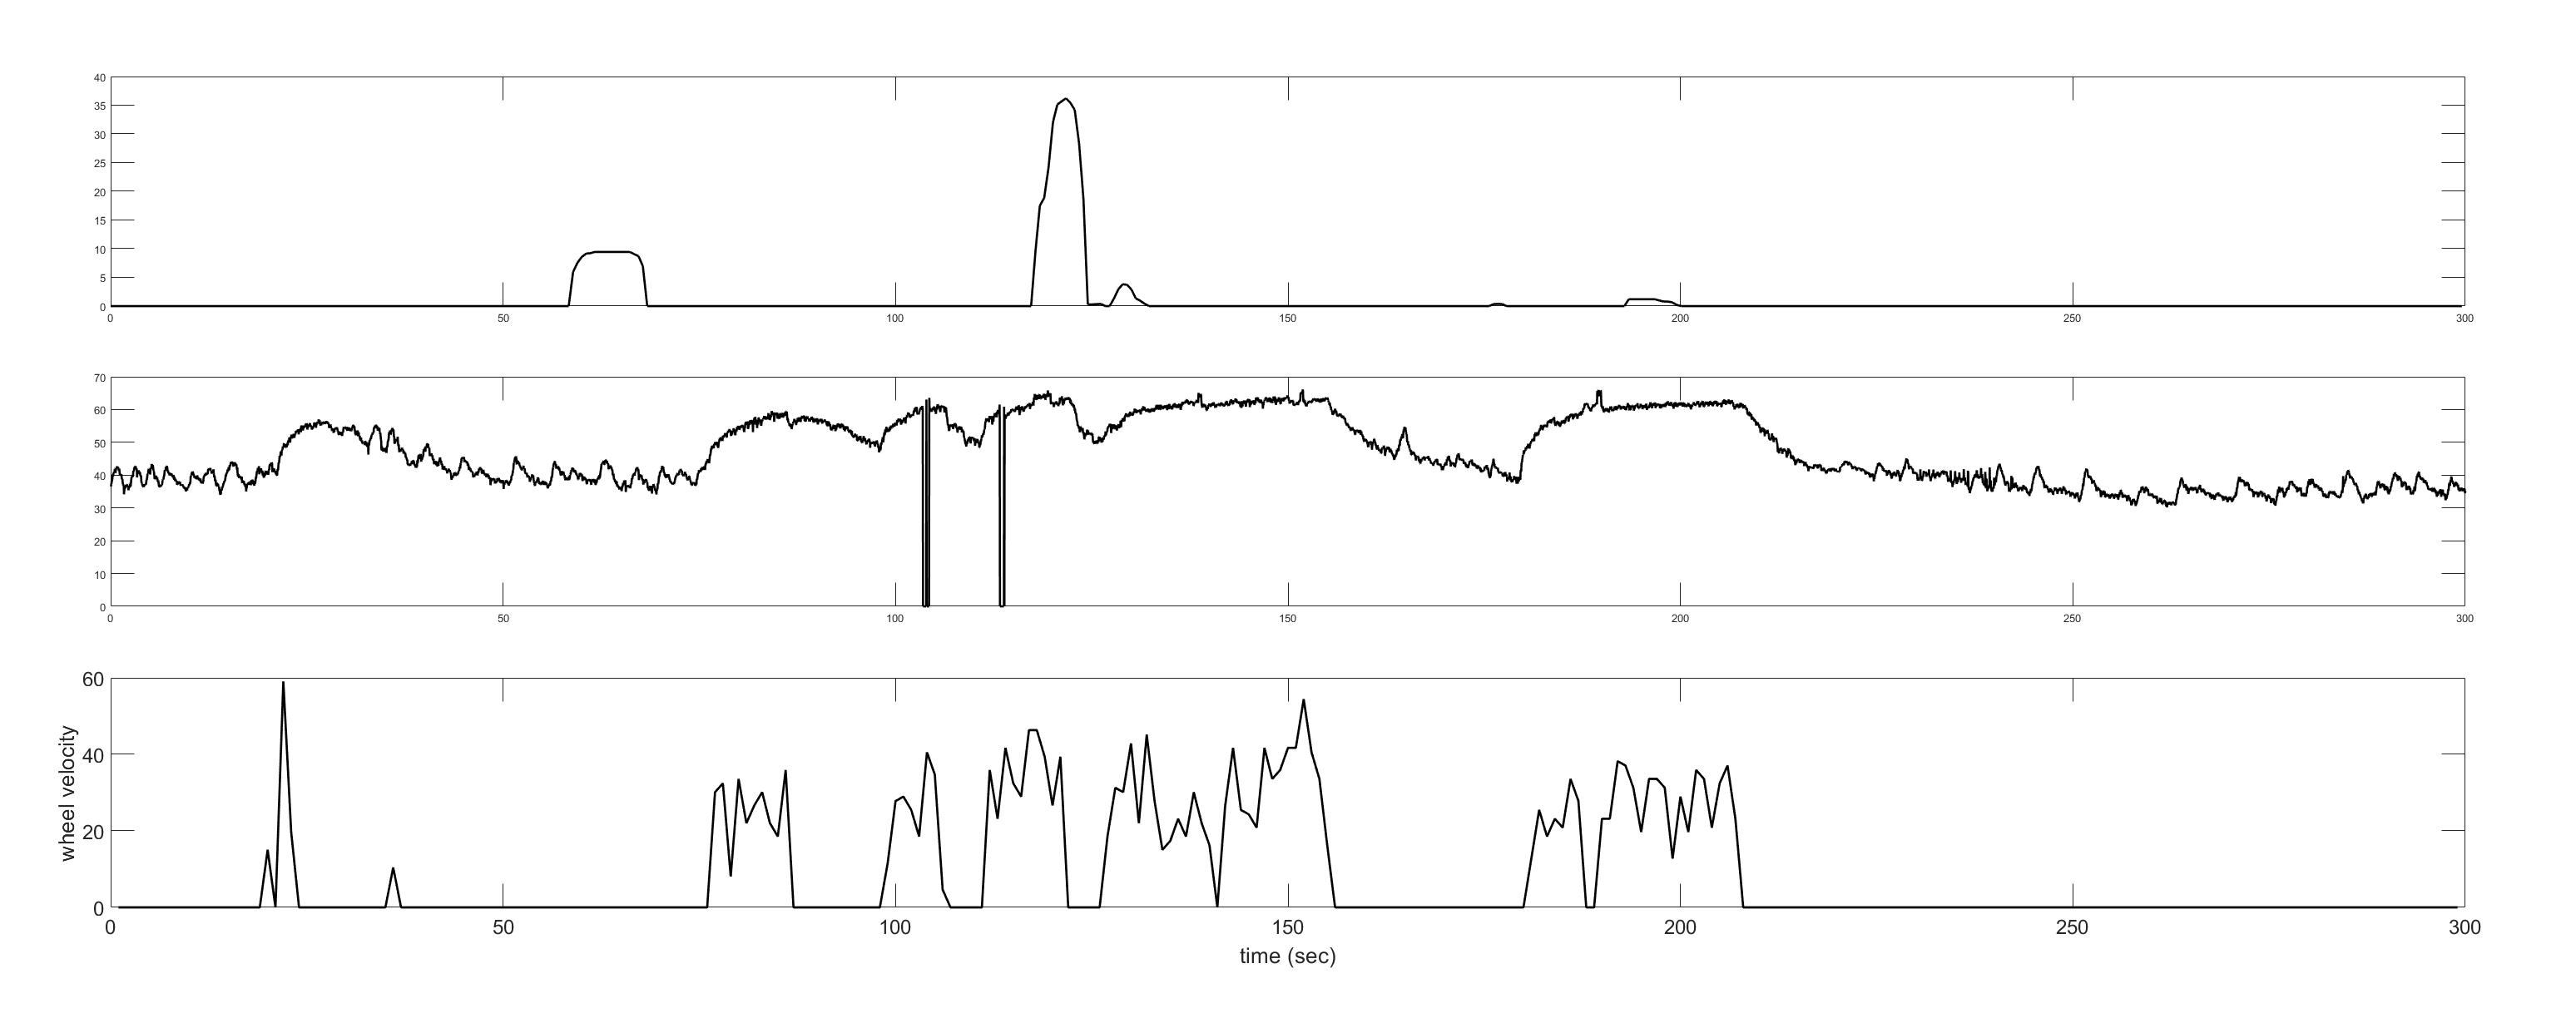

tiledlayout(3,1)

% top = perc fov
nexttile
plot(percframetimes, percEvts, 'LineWidth',2,'Color','k')


% mid = pupil
nexttile
plot (pupilframetimes, v26a.pupil, 'LineWidth',2,'Color','k')

% bottom = velocity
nexttile
plot(1:length(numbreaks),velocity, 'LineWidth',2,'Color','k')
ylabel('wheel velocity')
xlabel('time (sec)')
set(gca,'FontSize',18)

low pass filter the pupil data and fix error

pupilp = v26a.pupil

pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupil = figure

pupil =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1440 918 560 420]
       Units: 'pixels'

  Show all properties


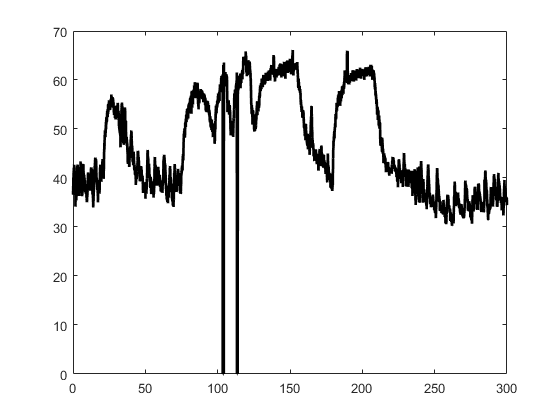

plot (pupilframetimes, pupilp, 'LineWidth',2,'Color','k')

for ii = 1:length(pupilp)
    if pupilp(ii) == 0
        pupilp(ii) = pupilp(ii-1)
    end
end

pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


pupilp =    36.5847
   37.1653
   37.3184
   38.1040
   38.0942
   38.6891
   39.1986
   40.2622
   39.6840
   40.0758


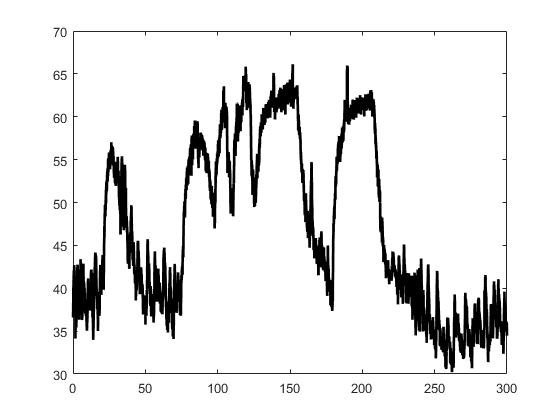


plot (pupilframetimes, pupilp, 'LineWidth',2,'Color','k')

pupilpl = lowpass(pupilp,0.00000000000000000000000000001)

pupilpl =    20.4802
   23.5401
   26.5117
   29.3239
   31.9154
   34.2378
   36.2582
   37.9602
   39.3431
   40.4212


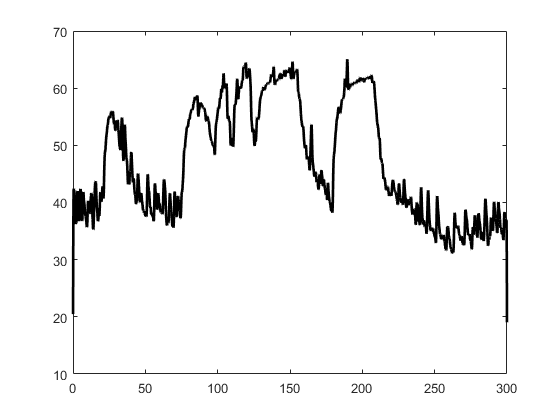

plot (pupilframetimes, pupilpl, 'LineWidth',2,'Color','k')

v26a.plot = tiledlayout(3,1)

v26a = struct with fields:
    pupil: [9000×1 double]
     plot: [1×1 TiledChartLayout]


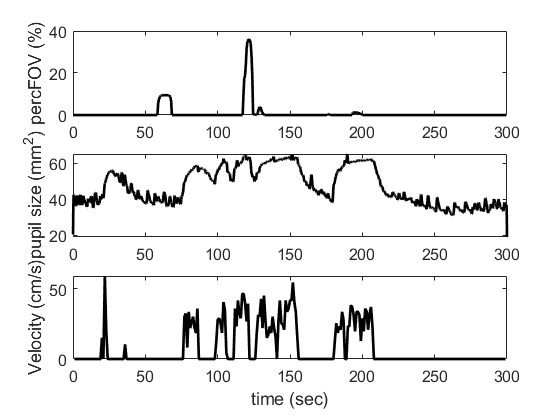


% top = perc fov
nexttile
plot(percframetimes, percEvts, 'LineWidth',2,'Color','k')
ylabel('percFOV (%)')
set(gca,'FontSize',12)

% mid = pupil
nexttile
plot (pupilframetimes, pupilpl, 'LineWidth',2,'Color','k')
ylabel('pupil size (mm^2)')
set(gca,'FontSize',12)

% bottom = velocity
nexttile
plot(1:length(numbreaks),velocity, 'LineWidth',2,'Color','k')
ylabel('Velocity (cm/s)')
xlabel('time (sec)')
set(gca,'FontSize',12)

v26.b